# Multiple Integrals

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Multivariable integrals extend the idea of adding up small pieces—from intervals in one dimension to regions and volumes in two and three dimensions. Instead of just finding the area under a curve, you might compute the area of an irregular region, the volume of a solid, or the total amount of a quantity spread across a surface or space. Switching to coordinate systems such as polar, cylindrical, or spherical can simplify these calculations when the shape has symmetry.

These tools appear everywhere in real applications. In mechanical engineering, you might use a double or triple integral to find the mass or center of mass of an object with non‑uniform density. In physics, you can compute things like work done by a force field or the charge in a region using integrals over areas or volumes. And in electrical engineering, integrals help determine properties such as inductance by accumulating effects over complex geometries. In fluid mechanics, they help determine the total amount of a substance or the flow rate through a region.

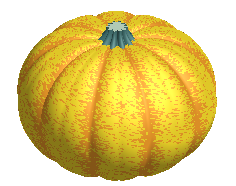 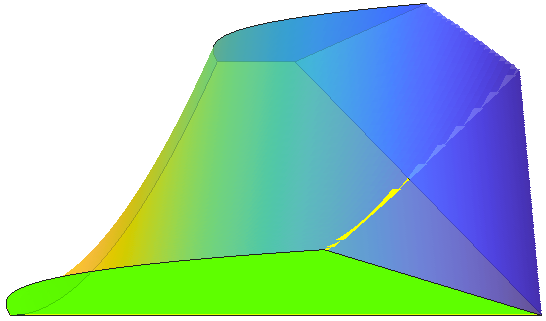 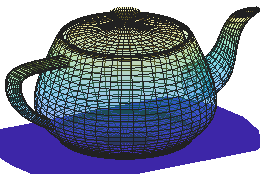

Multiple integrals provide powerful tools for modeling and solving real-world problems involving quantities distributed over regions in space and time.

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used by your professor for grading and completion checks.

## Motivation

A multiple integral lets you add up tiny pieces of a quantity spread across a region, like summing up all the little “tiles” that make up the surface area of a complex figure like the [Newell teapot](https://www.mathworks.com/help/matlab/visualize/displaying-complex-three-dimensional-objects.html).

 
figure
[verts, faces, cindex] = teapotGeometry;
p = patch(Faces=faces,Vertices=verts,FaceVertexCData=cindex);
p.FaceColor = "interp"; p.FaceAlpha = 0.3;
xlabel("inches")
ylabel("inches")
zlabel("inches")
zlim([-1 3])
axis equal
view(-30,20)
lengths = (verts(faces(:,2),:)-verts(faces(:,1),:));
widths = (verts(faces(:,3),:)-verts(faces(:,2),:));
tileAreas = sqrt(sum(cross(lengths,widths).^2,2));
area = round(vpa(sum(tileAreas)),2);
displayFormula(['"The surface area computed by summing the area of each rectangle is approximately "' "area" '" square inches."'])

$$The\;surface\;area\;computed\;by\;summing\;the\;area\;of\;each\;rectangle\;is\;approximately\;54.29\;square\;inches.$$

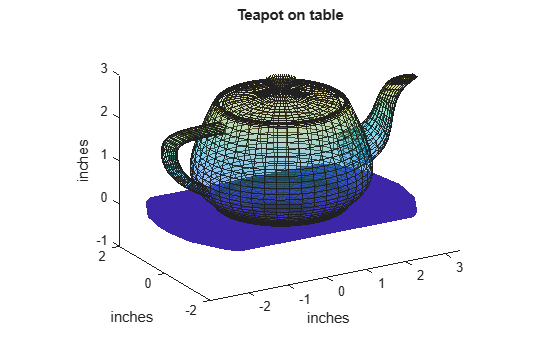

[X,Y,Z] = ellipsoid(0,0,1,2,2,2);
title("Teapot on table")
hold on
sphere = surf(X,Y,Z,Visible="off",EdgeColor="none",FaceColor="interp",FaceAlpha=0.6);
tableSurface = surf(X*1.5,Y*1.5,zeros(size(Z)),EdgeColor="none");
hold off
SphereVisible = false;
if SphereVisible
    areaCheck = round(vpa(4*pi*2^2),2);
    displayFormula(['"The surface area of a sphere of radius 2 is approximately "' "areaCheck" '" square inches."'])
    sphere.Visible = "on";
    xlim([-3 3.426])
    ylim([-2.0227 2.0227])
    zlim([-1 3.1678])
    tableSurface.Visible = "off";
    title("Teapot compared to a sphere")
else
    sphere.Visible = "off";
    tableSurface.Visible = "on";
    title("Teapot on table")
end

A triple integral does the same in 3‑D, letting you account for things like temperature, charge, or density that fill a solid. Or perhaps, calculate the volume of tea that a teapot can hold. In both cases, the integral acts like a super‑powered version of Riemann sums: you chop the region into tiny elements, evaluate the function there, and add everything up.

To make these calculations easier, you’ll often switch to coordinate systems that better match the symmetry of the region—like polar coordinates for circular shapes or cylindrical/spherical coordinates for pipes, cones, and spheres. This isn’t just a mathematical trick; it’s a way to simplify the shapes you’re integrating over so the integral becomes more manageable. Throughout this course, you’ll see that understanding *why* you’re integrating (mass? area? total energy?) and *what* region you're integrating over is just as important as computing the integral itself.

## Double Integral over a Region

Let's compute the double integral of $f(x, y) = x^2 + y^2$ over the region $R$ defined by $0 \leq x \leq 1$ and $0 \leq y \leq x^2$.

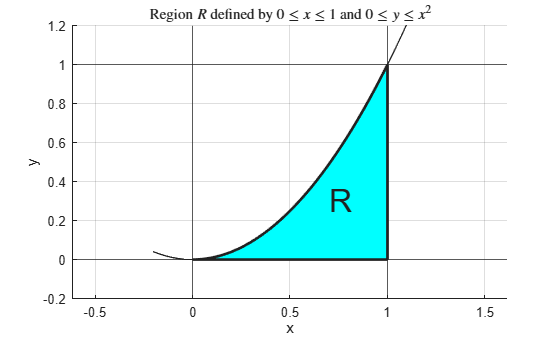

 
PlotR(0,1,0,1,@(x) x.^2,Ver=1);  % Defined in Local Helper Functions

First, we are going to move across this region in tiny $dy$ steps at a constant $x$ value. That means we move through the region by entering from the bottom, across the $y=0$ line, and exiting from the top, across the $y=x^2$ line. 

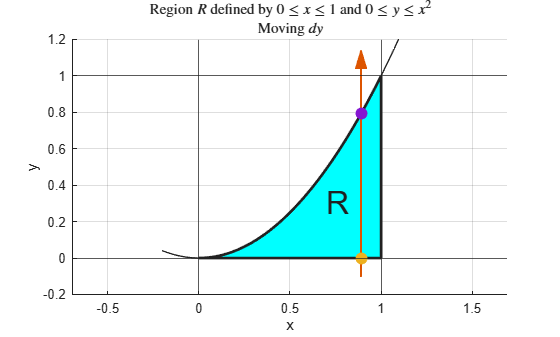

 
xVal = 0.89; Animate = true;
Arrow.LineWidth = 0.002;
Arrow.HeadWidth = 0.03;
Arrow.Start = [xVal -0.1];
Arrow.End = [xVal xVal];
Arrow.AxisValue = "dy";
try
    MyArrow1 = DrawArrowAcrossRegion(Arrow,MyArrow1,Pt1,Pt2,Animate);
catch
    [MyArrow1,Pt1,Pt2] = PlotR(0,1,0,1,@(x) x.^2,Ver=1,IncludeArrow=true,ArrowDef=Arrow,AnimateArrow=Animate,SubtitleStr="Moving $dy$");  % Defined in Local Helper Functions
end


$$\displaystyle \int_0^1\int_0^{x^2} x^2+y^2\; dy\;dx = \int_0^1 \left.x^2y + \frac{y^3}{3}\right|_0^{x^2}\; dx$$
 

 
$$\displaystyle = \int_0^1 \left.x^4 + \frac{x^6}{3}\; dx$$
 

 
$$\displaystyle = \left.\frac{x^5}{5} + \frac{x^7}{21}\right|_0^1$$
 

 
$$\displaystyle  = \frac{1}{5}+\frac{1}{21} = \frac{26}{105}$$
 

% Define the symbolic variables
syms x y

% Define the integrand
f = x^2+y^2;
% Define the limits of integration
xMin = 0;
xMax = 1;
yMin = 0;
yMax = x^2;
SymbolicIntegral = int(int(f,y,yMin,yMax),x,xMin,xMax);
displayFormula("int(int(f,y,yMin,yMax),x,xMin,xMax) == SymbolicIntegral")

$$\int_{0}^{1}\int_{0}^{x^{2}}\left(x^{2}+y^{2}\right)\;\text{d}y\;\text{d}x=\frac{26}{105}$$

### Iterated Integrals (Fubini's Theorem)

If $f(x,y)$ is suitably integrable over the region $D$, as when $|f(x,y)|$ has a finite integral over $D$, then [Fubini's Theorem](https://en.wikipedia.org/wiki/Fubini%27s_theorem) asserts that both the double integral and both forms of the iterated integral are equivalent:

 $\displaystyle \int\!\!\!\!\!\int_D f \, dA$ = $\displaystyle \int_a^b \left(\int_{g(y)}^{h(y)} f(x,y) \, dx\right) dy$ = $\displaystyle \int_g^h \left(\int_{p(x)}^{q(x)} f(x,y) \, dy\right) dx$.

This means not only can we choose to compute via iterated integrals, but we can also freely choose the order of our iterations to simplify calculations! 

By Fubini's theorem, we should get the same value if we integrate in the opposite order. This requires describing the region in a different way. First, we need to rewrite our curved bound(s) in terms of different variables. Here, we have $y = x^2$ so solving for $x$ gives $x = \sqrt{y}$. Therefore, we can define $R$ as the region with $0 \leq y \leq 1$ and $\sqrt{y} \leq x \leq 1$. Sketching a picture of the region helps keep track of which bounds are crossed in what order and which variables are constant.

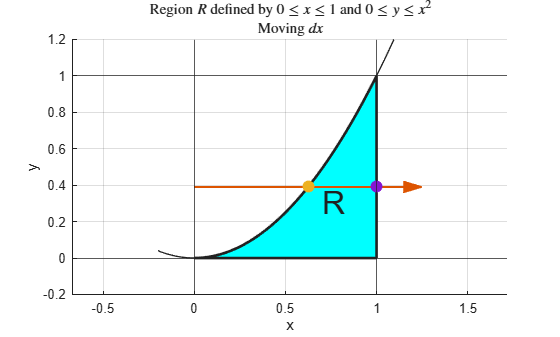

 
yVal = 0.39; Animate = false;
Arrow.LineWidth = 0.002;
Arrow.HeadWidth = 0.03;
Arrow.Start = [0 yVal];
Arrow.End = [1 yVal];
Arrow.AxisValue = "dx";
str = "or $0 \leq y \leq 1$ and $\sqrt{y} \leq x \leq 1$";
[MyArrow1,Pt1,Pt2] = PlotR(0,1,0,1,@(x) x.^2,Ver=1,IncludeArrow=true,ArrowDef=Arrow,AnimateArrow=Animate,SubtitleStr="Moving $dx$");  % Defined in Local Helper Functions

Notice that moving in the positive $x$-direction, we enter region $R$ by crossing the $x=\sqrt{y}$ line and we leave region $R$ by crossing the $x=1$ line, hence $\sqrt{y} \leq x \leq 1$ are the inner bounds of integration $dx$. The range of values for $y$ is $0 \leq y \leq 1$.

 
syms x y
f = x^2+y^2;
% Define the limits of integration
xMin = sqrt(y); xMax = 1; yMin = 0; yMax = 1;

% Compute the iterated integral
AltSymbolicIntegral = int(int(f,x,xMin,xMax),y,yMin,yMax);
AltSymStep = int(f,x,xMin,xMax);
% Print the results
displayFormula(["int(int(f,x,xMin,xMax),y,yMin,yMax) == int(AltSymStep,y,yMin,yMax)";...
    '"and"'; ...
    "int(AltSymStep,y,yMin,yMax) == AltSymbolicIntegral"; ...
    '"and thus,"'; ...
    "int(int(f,x,xMin,xMax),y,yMin,yMax) == AltSymbolicIntegral"])

$$\int_{0}^{1}\int_{\sqrt{y}}^{1}\left(x^{2}+y^{2}\right)\;\text{d}x\;\text{d}y=\int_{0}^{1}\left(y^{2}-\frac{y^{3/2}}{3}-y^{5/2}+\frac{1}{3}\right)\;\text{d}y$$

$$and$$

$$\int_{0}^{1}\left(y^{2}-\frac{y^{3/2}}{3}-y^{5/2}+\frac{1}{3}\right)\;\text{d}y=\frac{26}{105}$$

$$and\;thus,$$

$$\int_{0}^{1}\int_{\sqrt{y}}^{1}\left(x^{2}+y^{2}\right)\;\text{d}x\;\text{d}y=\frac{26}{105}$$

Geometrically, it is clear that the integral must be the same because we are always adding up the same values over infinitesimal rectangles, even if it is in a different order. The challenge arises when we consider that, in the limit as our number of rectangles approaches infinity, the question of whether it is mathematically true that reordering the sum will generate the same result becomes questionable. This is where requiring well-defined (i.e., finite) values for each iterated integral provides enough control that the result will hold. 

### Notation

Mathematically, multiple integrals are written symbolically as $\displaystyle \int\!\!\!\!\!\int_D f \, dA$, which represents the double integral of $f$ with respect to the differential area $dA$ over the two-dimensional region $D$, or $\displaystyle \int\!\!\!\!\! \int\!\!\!\!\! \int_R f \, dV$, which represents the triple integral of $f$ with respect to the differential volume $dV$ over the three-dimensional region $R$. While this communicates the integral, it needs to be expanded into an iterated integral, such as 


$$\displaystyle \int_{y=a}^{y=b} \!\!\int_{x=g(y)}^{x=h(y)} f(x,y) \; dx\, dy = \int_a^b \left(\int_{g(y)}^{h(y)} f(x,y) \, dx\right) dy$$
 

or 


$$\displaystyle \int_{x=a}^{x=b} \!\! \int_{y=p(x)}^{y=q(x)} \int_{z=g(x,y)}^{z=h(x,y)} f(x,y,z) \; dz \, dy\, dx = \int_a^b \left(\int_{p(x)}^{q(x)}  \left(\int_{g(x,y)}^{h(x,y)} f(x,y,z) \; dz\right) dy\right) dx$$
 

to support analytical solutions that follow approaches from single-variable calculus. 

### Practice

**Exercise 1**: Evaluate the integral $\displaystyle I = \int_0^2 \int_{x/2}^1(x+3y)\; dy \; dx$.

a. Sketch the region of integration.

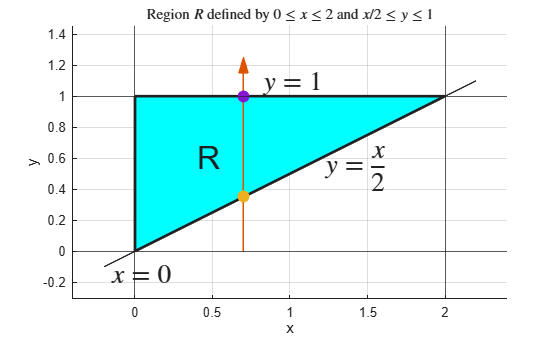

 
Arrow.LineWidth = 0.002;
Arrow.HeadWidth = 0.03;
Arrow.Start = [0.7 0];
Arrow.End = [0.7 1];
Arrow.AxisValue = "dy";
PlotR(0,2,0,1,@(x) x/2,Ver=2,ArrowDef=Arrow,IncludeArrow=true);

b. Apply Fubini's theorem to rewrite the integral $dx\; dy$.

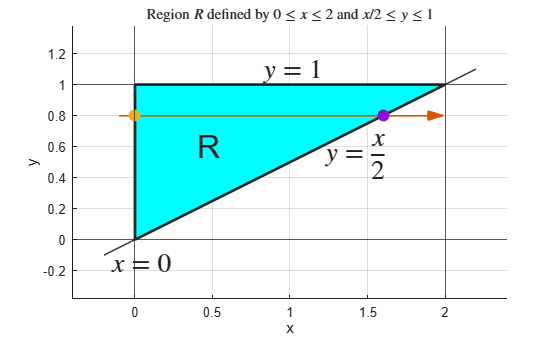

 
Arrow.LineWidth = 0.002;
Arrow.HeadWidth = 0.03;
Arrow.Start = [-0.1 0.8];
Arrow.End = [1.7 0.8];
Arrow.AxisValue = "dx";
PlotR(0,2,0,1,@(x) x/2,Ver=2,ArrowDef=Arrow,IncludeArrow=true);

**Solution:**

The region boundaries are $y=0$, $y=1$, $x=0$ and $y=x/2$ which is $x = 2y$. Therefore, 


$$I = \int_0^1 \int_0^{2y} (x+3y)\; dx\; dy$$


syms x y
xMin =  0;
xMax =  2*y;
yMin = 0;
yMax = 1;
CheckEx1b(xMin,xMax,yMin,yMax)   

$$Correct!\;\int_{0}^{1}\int_{0}^{2\;y}\left(x+3\;y\right)\;\text{d}x\;\text{d}y$$

c. Choose one of the integrals and compute the result.

**Solution:**


$$\int_0^1 \int_0^{2y} (x+3y)\; dx\; dy = \int_0^1 \left(\left.\frac{x^2}{2}+3xy\right|_0^{2y}\right) \; dy $$


 
$$= \int_0^1 \left(\frac{(2y)^2}{2}+3(2y)y\right) \; dy$$


 
$$=\int_0^1 8y^2 \; dy$$


 
$$=\left.8\frac{y^3}{3}\right|_0^1 = \frac{8}{3}$$



$$\int_0^2 \int_{x/2}^1(x+3y)\; dy \; dx = \int_0^2 \left(\left.xy+3\frac{y^2}{2}\right|_{x/2}^1\right)\; dx$$


 
$$= \int_0^2 x+\frac{3}{2} - \frac{x^2}{2}-\frac{3x^2}{8}\; dx$$


 
$$=\left.\frac{x^2}{2}+\frac{3}{2}x-\frac{7}{8}\frac{x^3}{3}\right|_0^2$$


 
$$=2+3-\frac{7}{8}\left(\frac{8}{3}\right) = 5-\frac{7}{3} = \frac{8}{3}$$


I = 8/3;
CheckEx1c(8/3)   

That is correct.


$$\int_{0}^{2}\int_{\frac{x}{2}}^{1}\left(x+3\;y\right)\;\text{d}y\;\text{d}x=\int_{0}^{2}\left(-\frac{\left(7\;x+6\right)\;\left(x-2\right)}{8}\right)\;\text{d}x$$

$$\int_{0}^{2}\int_{\frac{x}{2}}^{1}\left(x+3\;y\right)\;\text{d}y\;\text{d}x=\frac{8}{3}$$

**Exercise 2**: Evaluate the integral $\displaystyle I = \int_0^8 \int_{\sqrt[3]{x}}^2e^{y^2}\; dy \; dx$.

a. Sketch the region of integration.

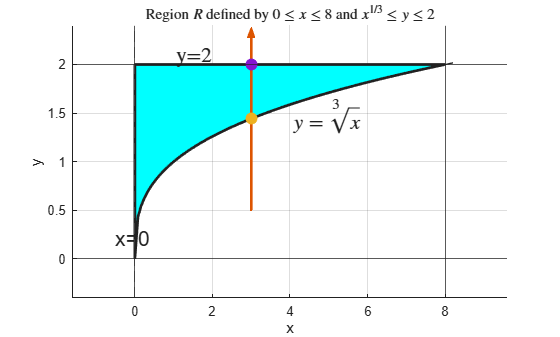

 
Arrow.LineWidth = 0.02;
Arrow.HeadWidth = 0.09;
Arrow.Start = [3 0.5];
Arrow.End = [3 2.1];
Arrow.AxisValue = "dy";
PlotR(0,8,0,2,@(x) x.^(1/3),Ver=3,ArrowDef=Arrow,IncludeArrow=true);

b. Apply Fubini's theorem to rewrite the integral $dx\; dy$.

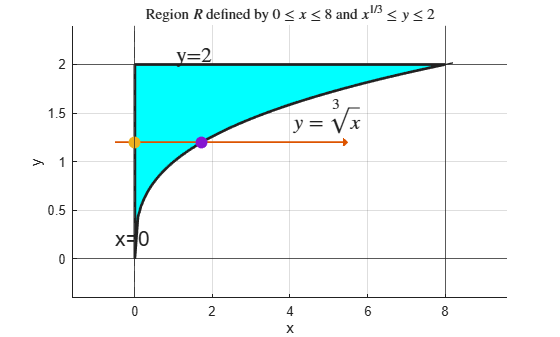

 
Arrow.LineWidth = 0.003;
Arrow.HeadWidth = 0.04;
Arrow.Start = [-0.5 1.2];
Arrow.End = [5 1.2];
Arrow.AxisValue = "dx";
PlotR(0,8,0,2,@(x) x.^(1/3),Ver=3,ArrowDef=Arrow,IncludeArrow=true);

$x=0$, $x=8$, $y=\sqrt[3]{x}$ $\Rightarrow$$x=y^3$, $y=2$


$$I = \int_0^2 \int_0^{y^3} e^{y^2}\; dx \; dy$$


syms x y
xMin =  0;
xMax =  y^3;
yMin = 0;
yMax = 2;
 
CheckEx2b(xMin,xMax,yMin,yMax)

$$Correct!\;\int_{0}^{2}\int_{0}^{y^{3}}e^{y^{2}}\;\text{d}x\;\text{d}y$$

c. Choose one of the integrals and compute the result.


$$I = \int_0^2 \int_0^{y^3} e^{y^2}\; dx \; dy = \left.\int_0^2 xe^{y^2}\right|_0^{y^3}\; dy$$


 
$$=\int_0^2 y^3e^{y^2}\; dy$$


Let $u = y^2$ then $du = 2y\; dy$, with $u(0) = 0$ and $u(2) = 4$, so the integral becomes:

 
$$I =\int_0^4 \frac{u}{2}e^u\; du$$


 
$$=\left.\frac{1}{2}(u-1)e^u\right|_0^4 $$



$$= \frac{3}{2}e^4+\frac{1}{2}$$


I = 3/2*exp(4)+1/2;
CheckEx2c(3/2*exp(4)+1/2)   

That is correct.


$$\int_{0}^{2}\int_{0}^{y^{3}}e^{y^{2}}\;\text{d}x\;\text{d}y=\int_{0}^{2}y^{3}\;e^{y^{2}}\;\text{d}y$$

$$\int_{0}^{2}\int_{0}^{y^{3}}e^{y^{2}}\;\text{d}x\;\text{d}y=\frac{3\;e^{4}}{2}+\frac{1}{2}$$

## Triple Integral Over a Volume

The same iterated integral approach works to calculate many integrals in three dimensions as well. As effective (or lazy?) mathematicians, we always want to reduce a new problem to some version of a problem we've already solved. If we naively apply this approach to triple integrals, we can see the double-integral step in the middle of the process. We are applying the same idea that chefs use to dice vegetables:

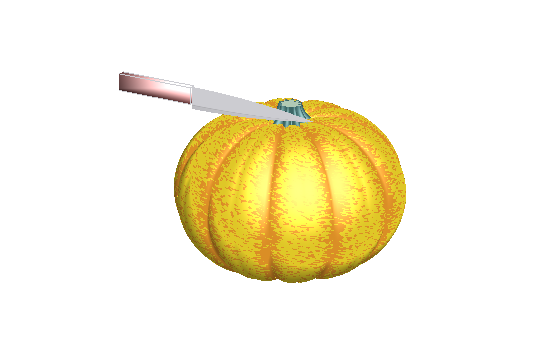

 
% Horizontal knife
xShift = -0.5;
yShift = 1;
zShift = 0.8;

clf
DrawKnife(xShift,yShift,zShift,"vertical")
hold on
[Cavity,Punkin,StemData,Cpunkin] = CreatePumpkin();
hold off
xlim([-1.2 1.2])
ylim([-1.2 1.2])

Now, to dice this pumpkin into cubes suitable for applying our Riemann sum integration methods, we have to pick a direction to slice. Any direction that we choose will give us the same total pumpkin, but the intermediate calculations--the choices that we have made about how to slice up the pumpkin--can lead to quite different appearances along the way.

  **Try**. Choose different slicing directions and viewing angles. What can you learn about this pumpkin? 

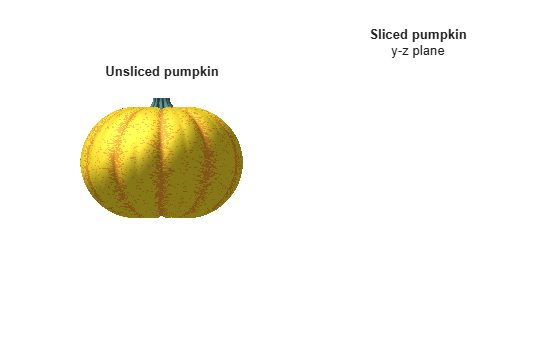

if ~exist("WholePumpkin","var") || ~exist("OrigPumpkin","var") || ~exist("StemCap","var") || ~isvalid(WholePumpkin) || ~isvalid(OrigPumpkin)
    figure
    tl = tiledlayout(1,2);
    nexttile
    if exist("Cavity","var")
        OrigPumpkin = DrawPumpkin(Cavity,Punkin,StemData,Cpunkin);
    else
        [Cavity,Punkin,StemData,Cpunkin] = CreatePumpkin();
        OrigPumpkin = gca;
    end
    title("Unsliced pumpkin")
    nexttile
    WholePumpkin = DrawPumpkin(Cavity,Punkin,StemData,Cpunkin);
    title("Sliced pumpkin")
    StemCap = WholePumpkin.Children(2).Vertices;
    StemFaces = WholePumpkin.Children(2).Faces;
    pause(0)
end
 
try
    Slice.Direction = "dx";
    WholePumpkin.View = [90 0]; WholePumpkin.Subtitle.String = "y-z plane";
    OrigPumpkin.View = WholePumpkin.View;
    Slice.Width = 0.1;
    Animate = true;     Slice.Location = 0;

    if Animate
        for pt = -1.1:Slice.Width:1.1 %#ok<UNRCH>
            Slice.Location = pt;
            WholePumpkin = PlotSlice(Slice,StemCap,StemData,Cavity,Punkin,WholePumpkin);
            pause(Slice.Width-0.03)
        end
    else
        WholePumpkin = PlotSlice(Slice,StemCap,StemData,Cavity,Punkin,WholePumpkin); %#ok<UNRCH>
    end
catch ME
    % Give an informative message to the user if sections are run out of order
    if contains(ME.message,"StemCap")
        warning("You must plot a pumpkin before slicing one.")
    else
        rethrow(ME)
    end
end

  **Try**. Plot various regions and explore them from different angles. After animating, use the slider to look at the slicing patterns more slowly.

 **Reflect**. What limitations were built into this code? What other visualizations would you like to see? Consider using the rotation option. 

### Riemann Integral Definition

Say $f(x,y,z)$ is a function defined on a closed, bounded region $R$ in space. Then we can define the Riemann integral of $f$ over $R$ as a limit of the summation over smaller and smaller subdivisions of $R$ into $N$ pieces $\Delta V_k$. Each point $(x_k,y_k,z_k) \in \Delta V_k$. 

$\displaystyle \int\!\!\!\!\!\int\!\!\!\!\!\int_R f(x,y,z)\; dV = \lim_{\text{max}|\Delta V_k|\to 0} \sum_{k=1}^{N}f(x_k,y_k,z_k)\Delta V_k$.

There is no new calculus involved in computing triple integrals when $f$ and $V$ are sufficiently nice, such that Fubini's Theorem applies. That said, determining how to set up the bounds of integration and the order of integration to compute the result successfully can be challenging for many students. It can also be confusing to track when a 'variable' is constant or changing. Do you remember your single variable calculus instructor requiring you to write the $dx$ or $dt$ or $du$ when setting up an integral? In multivariable calculus, it is critical to remember to track your infinitesimals because you cannot assume that a 'variable' present in the integrand is varying in the direction of integration! 

### Challenge: Visualization of Regions in 3D

The author of this script can personally attest that failing to draw the region of integration on a multivariable calculus exam can result in the wrong answer, even in her 11th year of higher education. Plotting regions on a computer in such a way that you can rotate, project, and slice the results can be a very useful approach to understanding a multiple integral. 

**Example:** Compute the volume of the region in the first octant bounded by $z = 5-x^2-y^2$ and $z=1$.

First, note that the first octant condition can be written as $x \geq 0$ and $y\geq 0$, which gives us minimum values for $x$ and $y$. Since $5 - 0 - 0 >1$, it also tells us that $z_{\text{max}}=5-x^2-y^2$ and $z_{\text{min}}=1$. It only remains to determine the maximum values of $x$ and $y$. First, observe that $z_{\text{max}}=z_{\text{min}}$ requires that $1 = 5-x^2-y^2$ or, equivalently, that $4 = x^2+y^2$. This is a circle of radius 2 centered at the origin, so the maximum values of $x$ and $y$ are 2. 

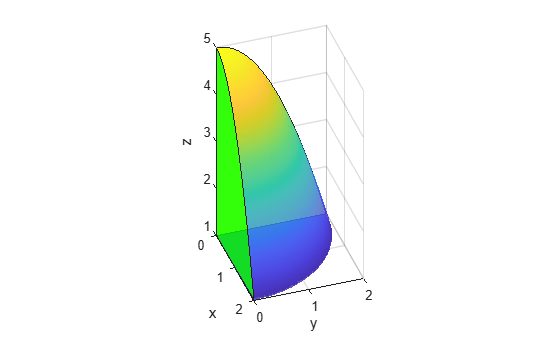

syms x y
xMin = 0;
xMax = 2;
yMin = 0;
yMax = 2;
zMax = 5-x^2-y^2;
zMin = 1;
 
DrawSolidRegion(xMin,xMax,yMin,yMax,zMin,zMax)
view([71.06 35.90])

  **Try**. Select the figure by clicking on it. Then click, hold, and drag to rotate the figure. What does it look like when you view it from different angles?

The volume is


$$V = \int_0^{2}\int_0^{\sqrt{4-y^2}}\int_1^{5-x^2-y^2}1\; dz\,dx\,dy$$
 


$$=\int_0^2\int_0^{\sqrt{4-y^2}}4-x^2-y^2\; dx \, dy$$
 


$$=\int_0^2 \left.(4-y^2)x-\frac{x^3}{3}\right|_0^{\sqrt{4-y^2}}\; dy = \int_0^2 \frac{2}{3}(4-y^2)^{3/2}\; dy$$



$$=2\pi$$
 

  **Try**. Plot various regions and explore them from different angles.

 **Reflect**. What limitations are built into this code?

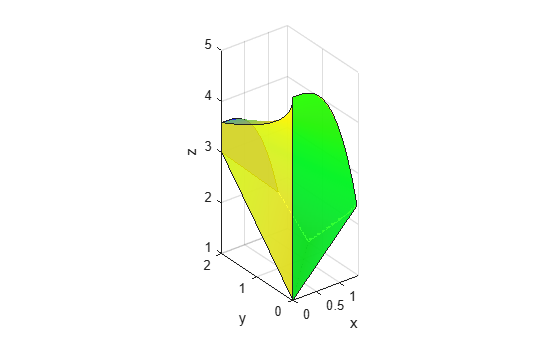

syms x y
xRange = [0 2];
xMin = xRange(1);
xMax = xRange(2);
yRange = [0 2];
yMin = yRange(1);
yMax = yRange(2);
zMax = 5-x^3-sqrt(y);
zMin = 1+abs(x-y);
 
DrawSolidRegion(xMin,xMax,yMin,yMax,zMin,zMax)

 **Exercise 3.** Find the volume of the figure in the first quadrant bounded by $z = 4x+y$, and $z=x^2$ with $y \leq 3$ and $x \leq 2$.

**Solution:**


$$\int_0^2\int_0^3\int_{x^2}^{4x+y}1\;dz\;dy\;dx = \int_0^2\int_0^34x+y-x^2\; dy \; dx$$


 
$$=\int_0^2 \left.4xy+\frac{y^2}{2}-x^2y\right|_0^3\; dx$$


 
$$=\int_0^2 12x+\frac{9}{2}-3x^2\; dx$$
 

 
$$=\left.6x^2+\frac{9}{2}x-x^3\right|_0^2$$
 

 
$$=24+9-8$$
 

 
$$=25$$
 

Exercise3Soln = 25;
 
CheckExercise3(Exercise3Soln)

That is correct.


$$\int_{0}^{2}\int_{0}^{3}\int_{x^{2}}^{4\;x+y}1\;\text{d}z\;\text{d}y\;\text{d}x\;=\;25$$

## Changing Coordinates

Up to this point, you've learned to compute double and triple integrals by slicing space neatly along perpendicular $x$-, $y$-, and $z$-axes. Cartesian coordinates are familiar and dependable—but they are not always the clearest way to describe a problem. Nature, geometry, and applications, as well as the previous example, often prefer circles, cylinders, and spheres over boxes.

Multiple integration in non-Cartesian coordinate systems is not about learning new integrals so much as learning to *listen to the geometry*. When a region has radial symmetry, angular repetition, or a natural center, forcing it into rectangular coordinates can obscure structure and complicate limits. Polar, cylindrical, and spherical coordinates realign our variables with the shape of the region, often turning complicated boundaries or integrands into simple ones.

There are two conceptual shifts to make as we move beyond Cartesian integration.

First, the variables themselves change meaning. Instead of measuring horizontal and vertical displacement, we may measure distance from an axis, angle of rotation, or distance from a point. These new coordinates describe position just as precisely—but from a different geometric viewpoint. Spherical, cylindrical, and polar coordinates are taught in the [Coordinate Systems](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Multivariable-Space-and-Functions&project=Space.prj&file=Scripts/CoordinateSystems.mlx) script in the [Multivariable: Space and Functions](https://www.mathworks.com/matlabcentral/fileexchange/180356-multivariable-space-and-functions) courseware.

Second—and this is the subtle but essential point—the volume (or area) element changes. In Cartesian coordinates, $dV$ is a rectangular prism that we can calculate as a product of the infinitesimals $dx$, $dy$, and $dz$. In other coordinate systems, however, describing the change in volume that occurs with an infinitesimal change in a coordinate looks different. 

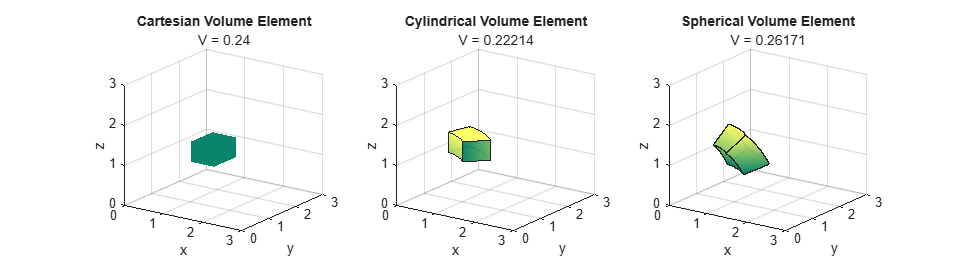

 
TiledVolumeElements

When we change coordinates, space stretches and compresses, and the integral must account for that distortion. 

### Jacobian

The Jacobian is the measure of how much area or volume is distorted by a coordinate transformation. Suppose we replace $(x,y)$ with new variables $(u,v)$. A small rectangle in the $(u,v)$ plane is usually not a rectangle in the $(x,y)$ plane. The coordinate transformation $u = f(x,y)$, $v=g(x,y)$ tells you where an individual point will map. The Jacobian tracks how the volume of a unit changes under this coordinate transform.


$$\text{Jacobian} = \left|\;\left(\matrix{\frac{\partial u}{\partial x} & \frac{\partial u}{\partial y} \cr \frac{\partial v}{\partial x} & \frac{\partial v}{\partial y}}\right)\; \right| = \frac{\partial u}{\partial x}\frac{\partial v}{\partial y} - \frac{\partial u}{\partial y} \frac{\partial v}{\partial x}$$


Conceptually, the Jacobian is doing one job: 

- Preserving total quantity under a change of variables.

Whether you are integrating mass, charge, probability, or volume, the Jacobian ensures that changing coordinates does not change the physical meaning of the integral—only its convenience. This is why Jacobian factors appear. They are not arbitrary corrections; they measure how much “space” each coordinate patch truly represents.

Once you see the Jacobian as a *geometric scaling factor*, rather than a mysterious determinant, non-Cartesian integration becomes not only manageable, but elegant. Seen this way, non-Cartesian integration is a natural continuation of what you already know. You are still accumulating quantities over regions—areas, volumes, mass, charge—but now you are choosing coordinates that respect the problem’s symmetry. Done thoughtfully, this change simplifies computation *and* deepens geometric understanding.

### Visualize Volume Elements

  **Try**. Observe the results for each volume form as you change the initial location and the step size in each direction.

#### a. Cartesian coordinates

Volume: $dx\; dy \; dz$

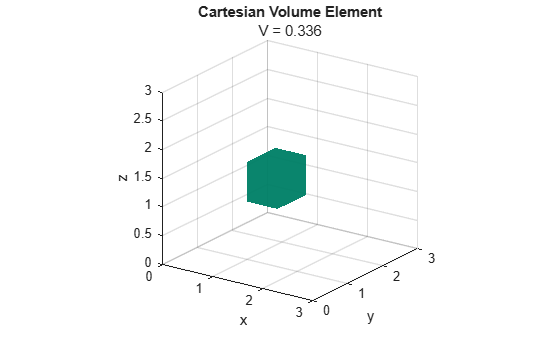

x0 = 1;
y0 = 1;
z0 = 1;
dx = 0.6;
dy = 0.8;
dz = 0.7;
figure
DrawCartesianVolumeElement("summer",dx,dy,dz,x0,y0,z0);  ZoomIn = false;
axis equal
if ~ZoomIn
    xlim([0 3])
    ylim([0 3])
    zlim([0 3])
end

#### b. Cylindrical coordinates

Volume: $r\; dr\; d\theta\; dz$

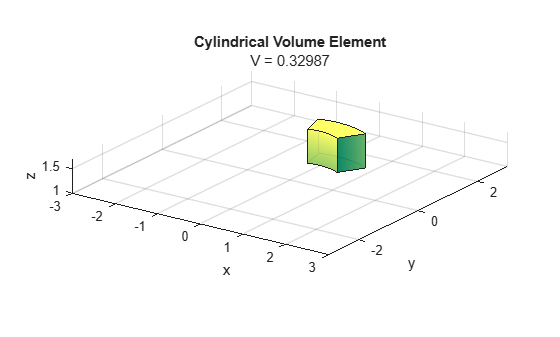

r0 = 1;
theta0 = 0.3333*pi;
z0 = 1;
dr = 0.6;
dtheta = 0.25*pi;
dz = 0.7;
figure
DrawCylindricalVolumeElement("summer",dr,dtheta,dz,r0,theta0,z0);  ZoomIn = false;
axis equal
if ~ZoomIn
    xlim([-3 3])
    ylim([-3 3])
end

#### c. Spherical coordinates

Volume: $\rho^2\sin(\phi) \; d\rho \; d\phi \; d\theta$

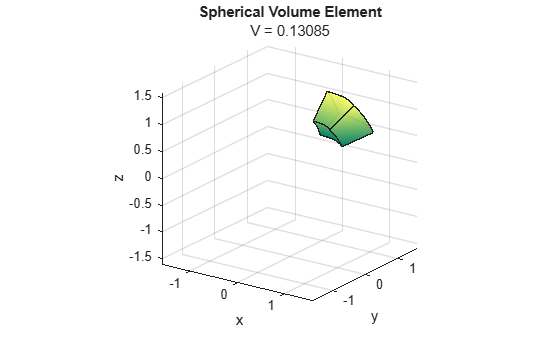

rho0 = 1;
phi0 = 0.25*pi;
theta0 = 0.25*pi;
drho = 0.6;
dphi = 0.125*pi;
dtheta = 0.25*pi;
figure
DrawSphericalVolumeElement("summer",drho,dphi,dtheta,rho0,phi0,theta0);   ZoomIn = false;
axis equal
if ~ZoomIn
    rhoMax = rho0+drho;
    xlim([-rhoMax rhoMax])
    ylim([-rhoMax rhoMax])
    zlim([-rhoMax rhoMax])
end

As we proceed, our guiding question will be simple and practical:

**What coordinate system best fits the shape of the region or the physics of the problem?**

Answer that well, and the integral often takes care of itself.

#### Example: An Integral in Cylindrical Coordinates

Consider the volume of a cone of height $h$ and base radius $R$. You can remember the formula for the volume of a cone, or you can remember a little bit of calculus:

$\displaystyle \text{Volume of a cone} = \int\!\!\!\!\!\int\!\!\!\!\!\int_{\text{Cone}} 1\; dV$.

To define the bounds, we need to consider the symmetries of a cone. Let's describe our cone by rotating a right triangle of height $h$ and base $R$ around the $z$-axis. 

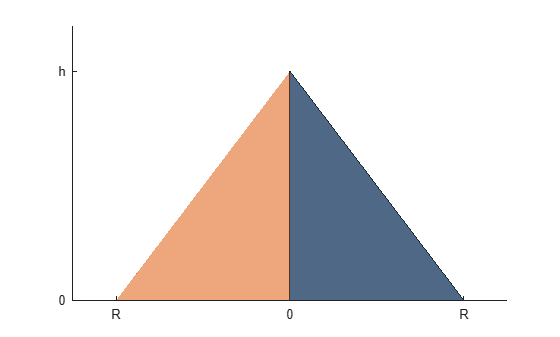

AnimateCone([0 0])  

We rotate the triangle all the way around the $z$-axis. This means we have the full range of possible values for $\theta$:

 $0 \leq \theta \leq 2\pi$. 

The base of our cone does depend on the height, but a consideration of similar triangles 

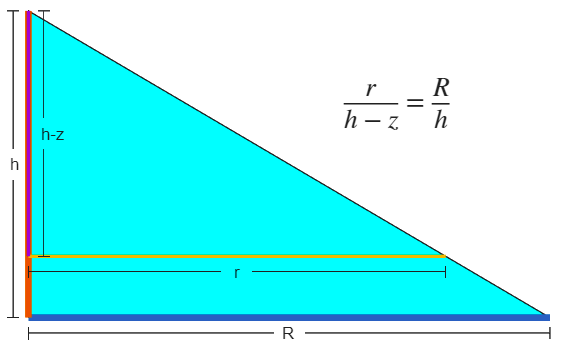

shows us that the radius $r$ at height $z$ must satisfy $\frac{r}{h-z} = \frac{R}{h} $

so, 

$0 \leq r \leq \frac{R(h-z)}{h}$ or, in simpler terms $0 \leq r \leq R\left(1-\frac{z}{h}\right)$. 

Finally, $0 \leq z \leq h$. Putting this all together, we have:

 $\displaystyle \int\!\!\!\!\!\int\!\!\!\!\!\int_{\text{Cone}} 1\; dV = \int_0^h\int_0^{R(1-z/h)}\int_0^{2\pi} r\; d\theta \; dr \; dz$.

Evaluating this iterated integral, we have:


$$\int_0^h\int_0^{R(1-z/h)}\int_0^{2\pi} r\; d\theta \; dr \; dz = \int_0^h\int_0^{R(1-z/h)}2\pi r \; dr \; dz$$


 
$$=\int_0^h \pi R^2\left(1-\frac{z}{h}\right)^2\; dz$$


Let $u = 1-\frac{z}{h}$ then $u(0) = 1-\frac{0}{h} = 1$ and $u(h) = 1-\frac{h}{h} = 0$ and $du = -\frac{1}{h}dz$, so

 
$$=\int_1^0 -\pi R^2 h u^2\; du$$


 
$$= \left.-\pi R^2 h\frac{u^3}{3}\right|_1^0 = \frac{\pi R^2 h}{3}$$


 **Exercise 4.** 

Calculate the integral:$\displaystyle \int_{-R}^R\int_{-\sqrt{R^2-x^2}}^{\sqrt{R^2-x^2}}\int_{-\sqrt{R^2-x^2-y^2}}^{\sqrt{R^2-x^2-y^2}} \;\;\;1\; dz \; dy \; dx$

**Solution:**

a. Which coordinate system is optimal for this problem?

CheckCoordinateChoice("Spherical",4)

Correct!
This integral simplifies elegantly in spherical coordinates.


Observe the symmetries of this domain. It will work nicely in spherical coordinates. 


$$\displaystyle \int_{-R}^R\int_{-\sqrt{R^2-x^2}}^{\sqrt{R^2-x^2}}\int_{-\sqrt{R^2-x^2-y^2}}^{\sqrt{R^2-x^2-y^2}} 1\; dz \; dy \; dx = \int_0^{R}\int_{0}^{\pi}\int_{0}^{2\pi}\rho^2\sin(\phi)\; d\theta \; d\phi \; d\rho$$


b. What value do you calculate? 

You can enter your solution in terms of `R` and `pi`. 


$$=\int_0^R\int_0^{\pi}2\pi\rho^2\sin(\phi)\; d\phi d\rho$$



$$=\int_0^R \left.2\pi\rho^2(-\cos(\phi))\right|_0^{\pi} = \int_0^R 4\pi \rho^2\; d\rho$$



$$= \frac{4}{3}\pi R^3$$


Notice how dramatically the problem simplifies. In Cartesian coordinates, the geometry of the sphere is buried inside square roots and nested limits. In spherical coordinates, the region becomes a rectangular box in $(\rho,\phi,\theta)$-space, and all of the geometric complexity is handled cleanly by the Jacobian.

This is the payoff of choosing coordinates that respect the symmetry of the problem.

syms R
CheckExercise4b( 4/3*pi*R^3)

Correct!


## Further Practice

Continue working on multiple integrals with a collection of applications in [Applications of Multiple Integrals](matlab:open('./MultipleIntegralsApplicationsSoln.mlx')).

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function [MyArrow,EntryPt,ExitPt] = PlotR(xMin,xMax,yMin,yMax,fExpr,opts)
arguments
    xMin (1,1) double
    xMax (1,1) double
    yMin (1,1) double
    yMax (1,1) double
    fExpr
    opts.IncludeArrow = false
    opts.ArrowDef = struct
    opts.AnimateArrow = false
    opts.SubtitleStr = ""
    opts.Ver = 1
end
MyArrow = nan;
EntryPt = nan;
ExitPt = nan;
if opts.IncludeArrow && class(opts.ArrowDef)~="struct"
    error("You must define an arrow to plot one.")
else
    figure
    f = fExpr; %@(x) x
    xVals = linspace(xMin,xMax,100);
    yVals = f(xVals);
    switch opts.Ver
        case 1
            if isscalar(opts.ArrowDef) || opts.ArrowDef.AxisValue == "dy"
                titleStr = "Region $R$ defined by $0 \leq x \leq 1$ and $0 \leq y \leq x^2$";
            elseif opts.ArrowDef.AxisValue == "dx"
                titleStr = "Region $R$ defined by $\sqrt{y} \leq x \leq 1$ and $0 \leq y \leq 1$";
            end

            opts.ArrowDef.CurveOrder = ["Left" "Top"];

            patch([xMin xVals xMax],[yMin yVals yMin],"c")
            hold on
            plot([xMin xMax],[yMin yMin],SeriesIndex="none",LineWidth=2) % Bottom of region
            plot([xMax xMax],[yMin yMax],SeriesIndex="none",LineWidth=2) % Right side of region
            text(0.7,0.3,"R","FontSize",24)
            hold off
            fInv = @(y) sqrt(y);
        case 2
            patch([0 0 2],[0 1 1],"c")
            opts.ArrowDef.CurveOrder = ["Right" "Bottom"];
            if isscalar(opts.ArrowDef) || opts.ArrowDef.AxisValue == "dy"
                titleStr = "Region $R$ defined by $0 \leq x \leq 2$ and $x/2 \leq y \leq 1$";
                text(1.2,0.55,"$y=\frac{x}{2}$",FontSize=20,Interpreter="latex")
            elseif opts.ArrowDef.AxisValue == "dx"
                titleStr = "Region $R$ defined by $0 \leq x \leq 2y$ and $0 \leq y \leq 1$";
                text(1.2,0.55,"$x=2y$",FontSize=20,Interpreter="latex")
            end
            text(0.4,0.6,"R",FontSize=24)
            text(-0.175,-0.15,"$x=0$",FontSize=20,Interpreter="latex")
            text(0.8,1.1,"$y=1$",FontSize=20,Interpreter="latex")
            hold on
            plot([xMin xMin],[yMin yMax],SeriesIndex="none",LineWidth=2) % Left side of region
            plot([xMin xMax],[yMax yMax],SeriesIndex="none",LineWidth=2) % Top side of region
            hold off
            fInv = @(y) 2*y;
        case 3
            patch([0 xVals 0],[0 yVals 2],"c")
            opts.ArrowDef.CurveOrder = ["Right" "Bottom"];
            text(-0.5,0.2,"x=0","FontSize",16)
            text(1,2.1,"y=2","FontSize",16,"Interpreter","latex")
            hold on
            plot([xMin xMin],[yMin yMax],SeriesIndex="none",LineWidth=2) % Left side of region
            plot([xMin xMax],[yMax yMax],SeriesIndex="none",LineWidth=2) % Top side of region
            hold off
            if isscalar(opts.ArrowDef) || opts.ArrowDef.AxisValue == "dy"
                titleStr = "Region $R$ defined by $0 \leq x \leq 8$ and $x^{1/3} \leq y \leq 2$";
                text(4,1.5,"$y=\sqrt[3]{x}$",FontSize=16,Interpreter="latex")
            elseif opts.ArrowDef.AxisValue == "dx"
                titleStr = "Region $R$ defined by $0 \leq x \leq y^3$ and $0 \leq y \leq 2$";
                text(4,1.5,"$x=y^3$",FontSize=16,Interpreter="latex")
            end
            fInv = @(y) y.^3;
    end
    hold on
    % Bounding box
    xline(xMin)  % xmin
    xline(xMax)  % xmax
    yline(yMin)  % ymin
    yline(yMax)  % ymax
    fplot(f,[-0.2+xMin 0.2+xMax],SeriesIndex="none")
    plot(xVals,f(xVals),SeriesIndex="none",LineWidth=2) % Functional edge of region
    xlabel("x");
    ylabel("y");
    title(titleStr,Interpreter="latex");
    if opts.SubtitleStr ~= ""
        subtitle(opts.SubtitleStr,Interpreter="latex")
    end
    MyScale = [xMax-xMin yMax-yMin];
    xlim([-0.2*MyScale(1)+xMin 0.2*MyScale(1)+xMax])
    ylim([-0.2*MyScale(2)+yMin 0.2*MyScale(2)+yMax])
    if opts.Ver ~= 3
        axis equal
    end
    grid on
    if opts.IncludeArrow
        Arrow = opts.ArrowDef;
        Arrow.Animate = opts.AnimateArrow;
        switch Arrow.AxisValue
            case "dx"
                if Arrow.CurveOrder(1) == "Left"
                    ArrowIn = [fInv(Arrow.Start(2)) Arrow.Start(2)];
                    ArrowOut = [xMax Arrow.End(2)];
                else
                    ArrowIn = [xMin Arrow.Start(2)];
                    ArrowOut = [fInv(Arrow.End(2)) Arrow.End(2)];
                end
            case "dy"
                if Arrow.CurveOrder(2) == "Top"
                    ArrowIn = [Arrow.Start(1) yMin];
                    ArrowOut = [Arrow.End(1) f(Arrow.End(1))];
                else
                    ArrowIn = [Arrow.Start(1) f(Arrow.Start(1))];
                    ArrowOut = [Arrow.End(1) yMax];
                end
        end
        [MyArrow,EntryPt,ExitPt,Arrow] = CreateArrow(Arrow,ArrowIn,ArrowOut);
        DrawArrowAcrossRegion(Arrow,MyArrow,EntryPt,ExitPt,Arrow.Animate);
    end
    hold off
end
end

function [MyArrow,EntryPt,ExitPt,Arrow] = CreateArrow(Arrow,EntryPoint,ExitPoint)
switch Arrow.AxisValue
    case "dx"
        xShift = [0 0 0.1 0.1 0.2 0.1 0.1];
        yShift = [Arrow.LineWidth -Arrow.LineWidth -Arrow.LineWidth -Arrow.HeadWidth 0 Arrow.HeadWidth Arrow.LineWidth];
    case "dy"
        xShift = [Arrow.LineWidth -Arrow.LineWidth -Arrow.LineWidth -Arrow.HeadWidth 0 Arrow.HeadWidth Arrow.LineWidth];
        yShift = [0 0 0.1 0.1 0.2 0.1 0.1];
    otherwise
        error("Unexpected Arrow.AxisValue.")
end
xPts = Arrow.Start(1) + xShift;
yPts = Arrow.Start(2) + yShift;
cData = colororder;
MyArrow = patch(xPts,yPts,cData(2,:),EdgeColor=cData(2,:));
EntryPt = scatter(EntryPoint(1),EntryPoint(2),80,"filled",SeriesIndex=3,Visible="off");
ExitPt = scatter(ExitPoint(1),ExitPoint(2),80,"filled",SeriesIndex=4,Visible="off");
Arrow.StepSize = norm(Arrow.End-Arrow.Start)/200;
end

function MyArrow = DrawArrowAcrossRegion(Arrow,MyArrow,EntryPoint,ExitPoint,Animate)
if Animate
    for tStep = 1:210
        switch Arrow.AxisValue
            case "dx"
                MyArrow.XData(3:end) = MyArrow.XData(3:end) + Arrow.StepSize;
            case "dy"
                MyArrow.YData(3:end) = MyArrow.YData(3:end) + Arrow.StepSize;
        end
        pause(0)
        if MyArrow.XData(end-2) >= EntryPoint.XData && MyArrow.YData(end-2) >= EntryPoint.YData
            EntryPoint.Visible = "on";
        end
        if MyArrow.XData(end-2) >= ExitPoint.XData && MyArrow.YData(end-2) >= ExitPoint.YData
            ExitPoint.Visible = "on";
        end
    end
else
    switch Arrow.AxisValue
        case "dx"
            MyArrow.XData(3:end) = MyArrow.XData(3:end) + Arrow.StepSize*210;
        case "dy"
            MyArrow.YData(3:end) = MyArrow.YData(3:end) + Arrow.StepSize*210;
    end
    EntryPoint.Visible = "on";
    ExitPoint.Visible = "on";
end
end

function CheckEx1b(xMin,xMax,yMin,yMax)
syms x y
xMinAns = 0;
xMaxAns = 2*y;
yMinAns = 0;
yMaxAns = 1;
if isAlways([0 2 x/2 1] == [xMin xMax yMin yMax],Unknown=false)
    disp("Incorrect, this is the default values.")
    disp("These are the bounds for the integral dy dx.")
    disp("What are the bounds for the integral dx dy?")
elseif isAlways([xMinAns xMaxAns yMinAns yMaxAns]==[xMin xMax yMin yMax],Unknown=false)
    displayFormula(['"Correct! "' "int(int(x+3*y,x,xMin,xMax),y,yMin,yMax)"])
else
    displayFormula('"Incorrect."')
    if isAlways([xMinAns xMaxAns]==[xMin xMax],Unknown=false)
        disp("You found the correct bounds for the inner integral, but what about the outer integral dy?")
        displayFormula("int(int(x+3*y,x,xMin,xMax),y,c,d)")
        disp("You want to find the absolute maximum yMax=c and minimum yMin=d values for y.")
    elseif isAlways([yMinAns yMaxAns]==[yMin yMax],Unknown=false)
        disp("You found the correct bounds for the outer integral, that is the absolute maximum and minimum values for y.")
        displayFormula("int(int(x+3*y,x,a(y),b(y)),y,yMin,yMax)")
        disp("How can you describe the bounds xMin=a(y) and xMax=b(y) at a fixed value y?")
    else
        disp("What are the bounds a(y), b(y), c, and d for the integral dx dy?")
        displayFormula("int(int(x+3*y,x,a(y),b(y)),y,c,d)")
    end
end
end

function CheckEx1c(myI)
arguments
    myI = NaN
end
syms x y
I = int(int(x+3*y,y,x/2,1),x,0,2);
I1 = int(int(x+3*y,y,2*x,1),x,0,2);
if isnan(myI)
    disp("This is the default value. Please enter the value of the integral.")
elseif abs(myI-I)<1e-10
    disp("That is correct.")
    Istep1 = int(x+3*y,y,x/2,1);
    displayFormula("int(int(x+3*y,y,x/2,1),x,0,2) == int(Istep1,x,0,2)")
    displayFormula("int(int(x+3*y,y,x/2,1),x,0,2) == I")
else
    displayFormula('"Incorrect."')
    if abs(myI+I) < 1e-10
        disp("It looks like you reversed the bounds on an integral.")
        disp("Please recheck and try again.")
    elseif abs(myI-I) < 1e-1
        disp("Please be more precise. What is the exact value of the integral?")
    elseif abs(myI-I1) < 1e-3
        disp("It looks like you confused the bounds on your integrals.")
        disp("Please check your computation.")
    else
        disp("Please check your computation and try again.")
    end
end
end

function CheckEx2b(xMin,xMax,yMin,yMax)
syms x y
xMinAns = 0;
xMaxAns = y^3;
yMinAns = 0;
yMaxAns = 2;
if isAlways([0 8 x^(1/3) 2] == [xMin xMax yMin yMax],Unknown=false)
    disp("These are the bounds for the integral dy dx.")
    disp("What are the bounds for the integral dx dy?")
elseif isAlways([xMinAns xMaxAns yMinAns yMaxAns]==[xMin xMax yMin yMax],Unknown=false)
    displayFormula(['"Correct! "' "int(int(exp(y^2),x,xMin,xMax),y,yMin,yMax)"])
else
    displayFormula('"Incorrect."')
    if isAlways([xMinAns xMaxAns]==[xMin xMax],Unknown=false)
        disp("You found the correct bounds for the inner integral, but what about the outer integral dy?")
        displayFormula("int(int(exp(y^2),x,xMin,xMax),y,c,d)")
        disp("You want to find the absolute maximum yMax=c and minimum yMin=d values for y.")
    elseif isAlways([yMinAns yMaxAns]==[yMin yMax],Unknown=false)
        disp("You found the correct bounds for the outer integral, that is the absolute maximum and minimum values for y.")
        displayFormula("int(int(exp(y^2),x,a(y),b(y)),y,yMin,yMax)")
        disp("How can you describe the bounds xMin=a(y) and xMax=b(y) at a fixed value y?")
    else
        disp("What are the bounds a(y), b(y), c, and d for the integral dx dy?")
        displayFormula("int(int(exp(y^2),x,a(y),b(y)),y,c,d)")
    end
end
end

function CheckEx2c(myI)
syms x y
I = int(int(exp(y^2),x,0,y^3),y,0,2);
I1 = int(int(exp(y^2),x,0,y^3),y,0,8);
if isnan(myI)
    disp("This is the default value. Please enter the value of the integral.")
elseif abs(myI-I)<1e-10
    disp("That is correct.")
    Istep1 = int(exp(y^2),x,0,y^3); %#ok<NASGU>
    displayFormula("int(int(exp(y^2),x,0,y^3),y,0,2) == int(Istep1,y,0,2)")
    displayFormula("int(int(exp(y^2),x,0,y^3),y,0,2) == I")
elseif abs(myI+I) < 1e-10
    disp("It looks like you reversed the bounds on an integral.")
    disp("Please recheck and try again.")
elseif abs(myI-I) < 1e-1
    disp("Please be more precise. What is the exact value of the integral?")
    displayFormula(['"You should use exp(x) for "' "exp(x)" '"."'])
elseif abs(myI-I1) < 1e-3
    disp("It looks like you confused the bounds on your integrals.")
    disp("Please check your computation.")
else
    disp("That is incorrect. Please check your computation.")
    disp("The correct solution is in terms of common functions.")
    displayFormula(['"You should use exp(x) for "' "exp(x)" '"."'])
end
end

function CheckExercise3(MySoln)
syms x y z
CorrectSoln = int(int(int(1,z,x^2,4*x+y),y,0,3),x,0,2);
IncorrectSoln1 = int(int(int(1,z,x,4*x+y),y,0,3),x,0,2);
IncorrectSoln2 = int(int(int(1,z,0,4*x+y),y,0,3),x,0,2);
IncorrectSoln3 = int(int(int(1,z,x^2,4*x+y),y,-3,3),x,-2,2);

if MySoln == CorrectSoln
    disp("That is correct.")
    displayFormula(["int(int(int(1,z,x^2,4*x+y),y,0,3),x,0,2)" '" = "' "CorrectSoln"])
elseif MySoln == 0
    disp("That is the default. The volume is not 0. Please try again.")
elseif MySoln == IncorrectSoln1
    disp("That is incorrect.")
    disp("Did you forget to square the lower bound?")
elseif MySoln == IncorrectSoln2
    disp("That is incorrect.")
    disp("Did you forget the lower bound for z?")
elseif MySoln == IncorrectSoln3
    disp("That is incorrect.")
    disp("The integral should be in the first quadrant with x, y, and z all greater than 0.")
elseif MySoln < 0
    disp("That is incorrect. The volume should be positive.")
else
    disp("That is incorrect. Please try again.")
end
end

function TiledVolumeElements
clf
figure(Position=[0 0 1000 280])
tiledlayout(1,3)
nexttile
DrawCartesianVolumeElement
nexttile
DrawCylindricalVolumeElement
nexttile
DrawSphericalVolumeElement
end

function AnimateCone(ViewOpt)
arguments
    ViewOpt = [-40 32];
end
thetas = linspace(0,2*pi,1200);
h = 10;
R = 4;
xVals = R*cos(thetas);
yVals = R*sin(thetas);
CData = colororder;
fill3(xVals,yVals,zeros(size(xVals)),CData(2,:),FaceAlpha=0.3);
hold on
% Create cone surface mesh and plot it
[zGrid,thetaGrid] = meshgrid(linspace(0,h,60), thetas);
rGrid = R*(1 - zGrid./h);
xGrid = rGrid .* cos(thetaGrid);
yGrid = rGrid .* sin(thetaGrid);
surf(xGrid, yGrid, zGrid, FaceColor=CData(2,:), FaceAlpha=0.3, EdgeColor="none");

triangle = fill3([0 0 xVals(1)], [0, 0, yVals(1)], [0, h, 0], CData(1,:));
view(ViewOpt)
hold off
xlim([-5 5])
ylim([-5 5])
zlim([0 12])
xticklabels(["R" 0 "R"])
xticks([-4 0 4])
yticks([-4 0 4])
yticklabels(["R" 0 "R"])
zticks([0 10])
zticklabels([0 "h"])
for theta = thetas
    triangle.Vertices(3,1:2) = [R*cos(theta) R*sin(theta)];
    pause(0)
end
end

function CheckCoordinateChoice(opt,prob)
arguments
    opt {mustBeMember(opt,["default" "Polar" "Cartesian" "Cylindrical" "Spherical"])}
    prob
end
if opt == "default"
    disp("Please try this problem.")
    return
end

switch prob
    case 4
        CorrectAns = "Spherical";
    case 5
        CorrectAns = "Cylindrical";
    case 6
        CorrectAns = "Polar";
    case 7
        CorrectAns = "Cartesian";
end
AnsIsCorrect = opt == CorrectAns;

if AnsIsCorrect
    disp("Correct!")
    switch opt
        case "Polar"
            disp("This 2D integral has rotational symmetry and works well in polar coordinates.")
        case "Cartesian"
            disp("This integral works well in Cartesian coordinates.")
        case "Cylindrical"
            disp("This integral has cylindrical symmetries.")
        case "Spherical"
            disp("This integral simplifies elegantly in spherical coordinates.")
    end
else
    disp("No, " + opt + " is not the best choice.")
    switch opt
        case "Polar"
            disp("What is the dimension of this integral?")
        case "Cartesian"
            disp("I don't want to work with all those square roots!")
            disp("Are there any symmetries to take advantage of?")
        case "Cylindrical"
            if CorrectAns == "Spherical"
                disp("Yes, there is x-y symmetry to this figure, but that still leaves square roots.")
                disp("Is there any other symmetry?")
            elseif CorrectAns == "Polar"
                disp("What is the dimension of this integral?")
            elseif CorrectAns == "Cartesian"
                disp("Are the region boundaries curves or straight lines?")
            else
                disp("What else have you considered?")
            end
        case "Spherical"
            if CorrectAns == "Cartesian"
                disp("Are the region boundaries curves or straight lines?")
            else
                disp("What symmetries appear in this problem?")
            end
        otherwise
            error("Unexpected option:" + opt)
    end
end
end

function CheckExercise4b(soln)
arguments
    soln = NaN;
end
if isnan(soln)
    disp("This is the default value. Please compute the integral.")
    return
end
syms R
if isAlways(soln==4/3*pi*R^3,"Unknown",false)
    disp("Correct!")
else
    disp("Please try again.")
end
end

function GraphicHandle = DrawSlice(XData,YData,ZData,SliceData,GraphicHandle,idx)
if idx == 2
    tmpX = XData(SliceData);
    tmpY = YData(SliceData);
    tmpZ = ZData(SliceData);
else
    tmpX = XData;
    tmpY = YData;
    tmpZ = ZData;
    tmpX(~SliceData) = nan;
    tmpY(~SliceData) = nan;
    tmpZ(~SliceData) = nan;
end
set(GraphicHandle.Children(idx), "XData", tmpX, "YData", tmpY, "ZData", tmpZ);
end

function Slice = MakeSlices(CapData,StemData,PumpkinData,CavityData,Slice)
Slice.Cap = CapData > Slice.Endpoints(1) & CapData < Slice.Endpoints(2);
Slice.Stem = StemData > Slice.Endpoints(1) & StemData < Slice.Endpoints(2);
Slice.Pumpkin = PumpkinData > Slice.Endpoints(1) & PumpkinData < Slice.Endpoints(2);
Slice.Cavity = CavityData > Slice.Endpoints(1) & CavityData < Slice.Endpoints(2);
end

function WholePumpkin = PlotSlice(Slice,StemCap,StemData,Cavity,Punkin,WholePumpkin)
Slice.Endpoints = [-Slice.Width/2 Slice.Width/2] + Slice.Location;
switch Slice.Direction
    case "dx"
        Slice = MakeSlices(StemCap(:,1),StemData.Xstem,Punkin.X,Cavity.X,Slice);
    case "dy"
        Slice = MakeSlices(StemCap(:,2),StemData.Ystem,Punkin.Y,Cavity.Y,Slice);
    case "dz"
        Slice = MakeSlices(StemCap(:,3),StemData.Zstem+StemData.heightratio^2,Punkin.Z,Cavity.Z,Slice);
end

if any(Slice.Cap == 1)
    WholePumpkin.Children(2).Visible = "on";
    WholePumpkin = DrawSlice(StemCap(:,1),StemCap(:,2),StemCap(:,3),Slice.Cap,WholePumpkin,2);
else
    WholePumpkin.Children(2).Visible = "off";
end

WholePumpkin = DrawSlice(StemData.Xstem,StemData.Ystem,StemData.Zstem+StemData.heightratio^2,Slice.Stem,WholePumpkin,3);
WholePumpkin = DrawSlice(Punkin.X,Punkin.Y,Punkin.Z,Slice.Pumpkin,WholePumpkin,4);
WholePumpkin = DrawSlice(Cavity.X,Cavity.Y,Cavity.Z,Slice.Cavity,WholePumpkin,5);

set(WholePumpkin, "XLim", [-1 1], "YLim", [-1 1], "ZLim", [-1 1]);
end